clear 
clc

addpath '.\INM'
addpath '.\SD'
addpath '.\FR'
addpath '.\functions'

load('forcing_terms.mat')
load('test_functions2.mat')
load('myFunctions.mat')

%Armijo
c1 = 1e-4;
rho = 0.5;
btmax = 50;
alpha0 = 5;

%Step for finite differences
h = 1e-8;

%Problem definition
n = 1000;
x0 = x5(n);
f = f5;
gradf = gf5;
Hessf = 0;

kmax = 5000;
tolgrad = 1.0E-6;
toldiffgrad = 1e-12;

% max number of iterations for the pcg
pcg_maxit = 200;

run_newton = true;
run_steepest = true;
run_fletcher = true;
%P5 -> Converges (with tolgrad or kmax easier)
%P13 -> Converges
%P14 -> Converge (con pcgmax=200,ci mette un botto)
%P23 

## Run Steepest Descent

if run_steepest
    tic
    disp('***Steepest Descent: start***')
    [xk_sd, fk_sd, gradfk_norm_sd, k_sd, xseq_sd, btseq_sd, fseq_sd, gfseq_sd] = ... 
        steepest_desc_bt(x0, f, gradf, alpha0, kmax, tolgrad, c1, rho, btmax);
    
    disp('***Steepest Descent: finished')
    toc
    disp('***SD: results')
    disp('*******')
    disp(['xk: ', mat2str(xk_sd)])
    disp(['f(xk): ', mat2str(fk_sd)])
    disp(['gradf(xk): ', mat2str(gradfk_norm_sd)])
    disp(['N of iterations: ', num2str(k_sd), '/', num2str(kmax), ';'])
    disp(['fseq: ', mat2str(fseq_sd)])
    disp(['gfseq: ', mat2str(gfseq_sd)])
    
    disp('****')
else
    disp("SD Method not runned")
end

***Steepest Descent: start***


Iteration 1 gf_norm: 2544.050663
Iteration 2 gf_norm: 284.127150
Iteration 3 gf_norm: 90.551329
Iteration 4 gf_norm: 265.301627
Iteration 5 gf_norm: 71.601655
Iteration 6 gf_norm: 58.278943
Iteration 7 gf_norm: 34.000361
Iteration 8 gf_norm: 23.936226
Iteration 9 gf_norm: 13.970467
Iteration 10 gf_norm: 7.182824
Iteration 11 gf_norm: 9.436626
Iteration 12 gf_norm: 3.216415
Iteration 13 gf_norm: 2.917936
Iteration 14 gf_norm: 2.723626
Iteration 15 gf_norm: 2.560197
Iteration 16 gf_norm: 2.368100
Iteration 17 gf_norm: 2.135052
Iteration 18 gf_norm: 1.828772
Iteration 19 gf_norm: 1.424402
Iteration 20 gf_norm: 0.939472
Iteration 21 gf_norm: 0.479055
Iteration 22 gf_norm: 0.684510
Iteration 23 gf_norm: 0.267548
Iteration 24 gf_norm: 0.290146
Iteration 25 gf_norm: 0.093195
Iteration 26 gf_norm: 0.134351
Iteration 27 gf_norm: 0.122088
Iteration 28 gf_norm: 0.103935
Iteration 29 gf_norm: 0.078869
Iteration 30 gf_norm: 0.048365
Iteration 31 gf_norm: 0.019337
Iteration 32 gf_norm: 0.003496
Iter

***Steepest Descent: finished


Elapsed time is 0.270211 seconds.


***SD: results


*******


xk: [0.278634466304384;1.6806255826515;0.114237988681753;-0.3640089717148;-0.471269689443372;-0.493988208652409;-0.498744784157298;-0.499737970868672;-0.499945362435147;-0.499988635178031;-0.499997678204062;-0.499999565687922;-0.499999958745253;-0.500000037703972;-0.500000051708419;-0.500000053081968;-0.500000052941172;-0.500000052759295;-0.500000052558675;-0.500000052409882;-0.500000052380603;-0.500000052442464;-0.500000052538645;-0.500000052625784;-0.500000052682887;-0.500000052710199;-0.500000052718944;-0.500000052719907;-0.500000052719006;-0.500000052718297;-0.500000052718041;-0.500000052718017;-0.500000052718044;-0.500000052718059;-0.500000052718062;-0.500000052718061;-0.50000005271806;-0.50000005271806;-0.50000005271806;-0.50000005271806;-0.50000005271806;-0.50000005271806;-0.50000005271806;-0.50000005271806;-0.50000005271806;-0.50000005271806;-0.50000005271806;-0.50000005271806;-0.50000005271806;-0.50000005271806;-0.50000005271806;-0.50000005271806;-0.50000005271806;-0.500000052

f(xk): 9.85120171786874e-13


gradf(xk): 8.47118325461194e-07


N of iterations: 51/5000;


fseq: [3562.40097336771 904.391587635699 649.036931009779 200.149527919805 62.1644800456818 30.5300484958029 11.409920528091 6.26998006286224 2.87072538861268 1.39695866169716 1.08342640896852 0.458173034480674 0.303836843924518 0.212073962960466 0.154549620687871 0.113626648235444 0.0833864930792166 0.0594317182065559 0.0390770465218581 0.0226291545149508 0.0118482404960319 0.00957700484679054 0.00397156763866484 0.00270418158274864 0.00124338380336424 0.000327236796847497 0.000274924522126972 0.000206959891813026 0.000128867198151633 5.66636589458528e-05 1.38885989801449e-05 3.11213612470673e-06 1.85404536387783e-06 1.03455490533514e-06 5.45928007649725e-07 3.33892767299836e-07 1.78333769123543e-07 1.33345280253535e-07 6.52266371617261e-09 2.51109687804313e-09 6.34595030179221e-10 4.90489068843592e-10 4.25437002589911e-10 4.18836260887209e-10 7.83883558097926e-11 2.01491661350759e-11 6.79550254971769e-12 4.33693674101174e-12 2.76518356929853e-12 1.67464679021832e-12 9.85120171786874e

gfseq: [2544.05066346241 284.127149514251 90.5513289379646 265.301627214725 71.6016550119957 58.2789432323291 34.000361063937 23.9362262614609 13.9704673485121 7.18282363122172 9.43662636446511 3.21641525337529 2.91793606411797 2.72362644242068 2.56019678363725 2.3680998086086 2.1350518792258 1.82877174368747 1.42440201201919 0.939471538895945 0.479055208720999 0.684509574014097 0.267548020155774 0.290145523508312 0.0931946440504815 0.134351111341028 0.122088494334437 0.103935030021223 0.0788690014473014 0.0483646443078567 0.0193373289378148 0.00349603989174912 0.00476198968897275 0.00291226099455884 0.00137347884918357 0.00146009111750408 0.000580787080937835 0.00155345139861319 0.000258084120622608 0.000140089122917492 4.37834909995495e-05 4.4811830409433e-05 4.6774201127847e-05 5.13551369878158e-05 7.05851520686425e-06 7.53808521270016e-06 2.37618360007102e-06 2.10925222654602e-06 1.7381736299724e-06 1.29257411648268e-06 8.47118325461194e-07]


****


## Run Fletcher Reeves

if run_steepest
    tic
    disp('***Fletcher Reeves: start***')
    [xk_fr, fk_fr, gradfk_norm_fr, k_fr, xseq_fr, btseq_fr, fseq_fr, gfseq_fr] = ... 
        fletcher_reeves(x0, f, gradf, alpha0, kmax, tolgrad, c1, rho, btmax);
    
    disp('***Fletcher Reeves: finished')
    toc
    disp('***FR: results')
    disp('*******')
    disp(['xk: ', mat2str(xk_fr)])
    disp(['f(xk): ', mat2str(fk_fr)])
    disp(['gradf(xk): ', mat2str(gradfk_norm_fr)])
    disp(['N of iterations: ', num2str(k_fr), '/', num2str(kmax), ';'])
    disp(['fseq: ', mat2str(fseq_fr)])
    disp(['gfseq: ', mat2str(gfseq_fr)])
    
    disp('****')
else
    disp("FR Method not runned")
end

***Fletcher Reeves: start***


Iteration 1 gf_norm: 2544.050663
Iteration 2 gf_norm: 1629.412206
Iteration 3 gf_norm: 671.635760
Iteration 4 gf_norm: 1387.409666
Iteration 5 gf_norm: 1387.409666
Iteration 6 gf_norm: 2402.818215
Iteration 7 gf_norm: 1224.443654
Iteration 8 gf_norm: 77.489695
Iteration 9 gf_norm: 67.420311
Iteration 10 gf_norm: 59.258709
Iteration 11 gf_norm: 12.772631
Iteration 12 gf_norm: 12.175404
Iteration 13 gf_norm: 7.645364
Iteration 14 gf_norm: 3.988631
Iteration 15 gf_norm: 1.420778
Iteration 16 gf_norm: 0.895578
Iteration 17 gf_norm: 1.275113
Iteration 18 gf_norm: 1.270446
Iteration 19 gf_norm: 0.979180
Iteration 20 gf_norm: 1.380640
Iteration 21 gf_norm: 1.365528
Iteration 22 gf_norm: 1.175760
Iteration 23 gf_norm: 1.126280
Iteration 24 gf_norm: 0.922769
Iteration 25 gf_norm: 1.019532
Iteration 26 gf_norm: 1.011778
Iteration 27 gf_norm: 0.818920
Iteration 28 gf_norm: 0.704179
Iteration 29 gf_norm: 0.479184
Iteration 30 gf_norm: 0.295043
Iteration 31 gf_norm: 0.357934
Iteration 32 gf_norm: 0

***Fletcher Reeves: finished


Elapsed time is 10.075056 seconds.


***FR: results


*******


xk: [0.127328089679276;1.34955953496201;1.27872865494307;0.21633256403749;0.276669789047327;1.46058422751286;0.838469982193823;0.648762219482618;1.26603204905115;0.94365984567573;0.783959176007547;1.17903353966377;0.972901120813019;0.846596872290731;1.13343712082162;0.984354958695856;0.881718433216082;1.10594543980217;0.989887258307647;0.903963180543829;1.08770309019792;0.992949876553629;0.91924835485934;1.07475977504815;0.9948132777465;0.930373780102809;1.065116947979;0.996028280254181;0.938824222064083;1.05766178050885;0.996863581323453;0.945456026797762;1.05172966824078;0.997461351710186;0.950797373588727;1.04689883475767;0.997904024366824;0.955189851945811;1.04288926979651;0.998240842451147;0.958865231232418;1.03950894725516;0.998503001465808;0.961985557177327;1.03662027171707;0.998710962635708;0.964667839348483;1.0341232160829;0.998878750823196;0.966997487704974;1.03194416407456;0.999015965737321;0.96904044868115;1.03002531221105;0.999129586705539;0.970845854172651;1.0283231355486

f(xk): 8.53975328466621e-09


gradf(xk): 9.98565338881971e-07


N of iterations: 3921/5000;


fseq: [3562.40097336771 3260.87750492716 2848.88836769456 2610.05752113596 2610.05752114271 2525.61630699842 993.472834836929 316.486799305155 96.7344374753634 27.6525706209114 4.61680169244098 3.33193342252608 1.5242362045326 1.02252459155453 0.304536323599157 0.18920159537742 0.172810317972774 0.16409693476828 0.12241687196085 0.108971813593669 0.102862531714338 0.0875277514544022 0.0860866011171267 0.0716463951892273 0.0714360007187817 0.0711233609203993 0.0536350377127795 0.0342602378427962 0.0213543543716538 0.0137228164268533 0.0128433247358235 0.012316367884066 0.0111398068142529 0.0108691376231418 0.00810676935594408 0.00735610972776742 0.00709381439235388 0.00593620965281814 0.00587869112216368 0.004731782433399 0.00465540653618772 0.004620666157404 0.00461194005602822 0.00438010657557612 0.00421728789408429 0.00407936570584162 0.00315662687248568 0.00297826680577556 0.00295645675306483 0.00256971329624831 0.00228981755701797 0.0016911988167064 0.00145707486227223 0.0012426811

gfseq: [2544.05066346241 1629.41220634175 671.635760298833 1387.40966569517 1387.40966570383 2402.81821498297 1224.44365429628 77.4896950756872 67.4203109555109 59.2587093577529 12.7726313868785 12.1754035131385 7.64536368348088 3.98863118139646 1.42077805876034 0.895578115646318 1.27511341087517 1.27044642540983 0.979179977785361 1.38064023154712 1.36552756882458 1.17576021975171 1.12628024241989 0.922768846079709 1.0195315907067 1.01177777374063 0.818919991494539 0.704178592224059 0.479183979245641 0.295043214774647 0.357933700082757 0.363659985702801 0.315215330977992 0.291122349270441 0.21946038136209 0.242565915154646 0.245443227899297 0.240587624866606 0.240362312150963 0.160050123089924 0.175337440907589 0.192092238603973 0.201255597742788 0.185409082524286 0.191283256640505 0.18353323042286 0.132562509210852 0.143941604789304 0.160472821592862 0.135128180354571 0.117440435745298 0.0890464784039861 0.0774991103069381 0.0709584695666036 0.0731531420065804 0.0475813348345026 0.049

****


## Run the Newton

if run_newton
%     fterms = @(gradf, x, k) 0.5;
    fterms = @(gradfk, k) min(0.5, sqrt(norm(gradfk)));
%     fterms = @(gradfk, k) min(0.5, norm(gradfk));
    
    % options for finite differences
    FDgrad = 'c';
    FDHess = 'fw';
    
    disp('***NEWTON F.D. options***')
    disp(['FDgrad: ', FDgrad])
    disp(['FDHess: ', FDHess])
    
    disp('***Newton: start***')
    tic
    [xk, fk, gradfk_norm, k, xseq, btseq, fseq, gfseq] = ...
        innewton_general(x0, f, gradf, Hessf, kmax, ...
        tolgrad, toldiffgrad, c1, rho, btmax, FDgrad, FDHess, h, fterms, pcg_maxit);
    
    disp('***IN. newton: finished')
    toc
    disp('***newton: results')
    disp('*******')
    disp(['xk: ', mat2str(xk)])
    disp(['f(xk): ', mat2str(fk)])
    disp(['gradf(xk): ', mat2str(gradfk_norm)])
    disp(['N of iterations: ', num2str(k), '/', num2str(kmax), ';'])
    disp(['fseq: ',mat2str(fseq)])
    disp(['gfseq: ',mat2str(gfseq)])

    disp('****')
else
    disp("Newton Method not runned")
end

***NEWTON F.D. options***


FDgrad: c


FDHess: fw


***Newton: start***


Hessian PD
pcg converged at iteration 1 to a solution with relative residual 0.1.
Iteration 0 gf_norm: 266.142131
Hessian PD
pcg converged at iteration 1 to a solution with relative residual 0.18.
Iteration 1 gf_norm: 73.040836
Hessian PD
pcg converged at iteration 2 to a solution with relative residual 0.093.
Iteration 2 gf_norm: 16.507035
Hessian PD
pcg converged at iteration 2 to a solution with relative residual 0.044.
Iteration 3 gf_norm: 3.114655
Hessian PD
pcg converged at iteration 2 to a solution with relative residual 0.089.
Iteration 4 gf_norm: 0.560647
Hessian PD
pcg converged at iteration 2 to a solution with relative residual 0.2.
Iteration 5 gf_norm: 0.128681
Hessian PD
pcg converged at iteration 2 to a solution with relative residual 0.11.
Iteration 6 gf_norm: 0.024984
Hessian PD
pcg converged at iteration 3 to a solution with relative residual 0.063.
Iteration 7 gf_norm: 0.005672
Hessian PD
pcg converged at iteration 2 to a solution with relative residual 0.051.
Iterat

***IN. newton: finished


Elapsed time is 7254.958058 seconds.


***newton: results


*******


xk: [-0.390616181403096;-0.476945634750101;-0.495208337286002;-0.498987722936154;-0.499815793015915;-0.499976878406922;-0.500010415198391;-0.500033103947516;-0.500028747727366;-0.500037753052235;-0.500039971594548;-0.500036798317032;-0.500040715373563;-0.500038783883141;-0.500038753994466;-0.500040872952953;-0.500039324556464;-0.5000397943604;-0.500039660036791;-0.500039649689915;-0.500039699335727;-0.500039671402458;-0.500039678805408;-0.500039678366175;-0.500039677924322;-0.500039678133232;-0.500039678073652;-0.500039678090874;-0.500039678086398;-0.500039678086299;-0.500039678085688;-0.500039678087248;-0.500039678085575;-0.500039678086039;-0.500039678085985;-0.500039678085623;-0.500039678092742;-0.500039678090865;-0.500039678048744;-0.500039678092804;-0.500039678164078;-0.500039678076034;-0.500039677934559;-0.500039678101866;-0.500039678327858;-0.500039678093661;-0.500039677708356;-0.50003967807222;-0.50003967860878;-0.500039678064607;-0.50003967747211;-0.500039678169887;-0.500039678

f(xk): 6.91949809819584e-07


gradf(xk): 0.00130815174710451


N of iterations: 13/5000;


fseq: [815.358524220853 105.765429546765 9.02482549491404 0.518733185635884 0.0253924891460376 0.00146524806071814 8.47219650497982e-05 7.72457375800461e-06 1.45818724989976e-06 6.91949809833314e-07 6.91949809828735e-07 6.91949809824246e-07 6.91949809819584e-07]


gfseq: [266.142131241093 73.0408359468842 16.5070350768416 3.11465517176802 0.560646717911984 0.128681016145155 0.02498404644538 0.0056718577017294 0.00201689724295892 0.00130815174757768 0.00130815174666981 0.00130815174763421 0.00130815174710451]


****


disp('===========================================================================================================================================================================')

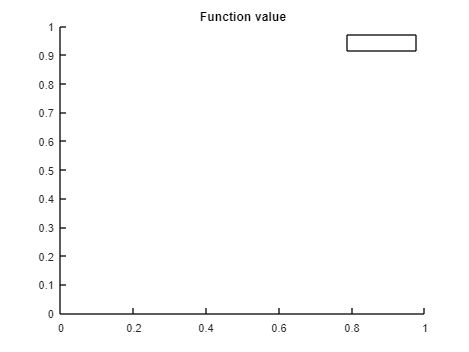

cla

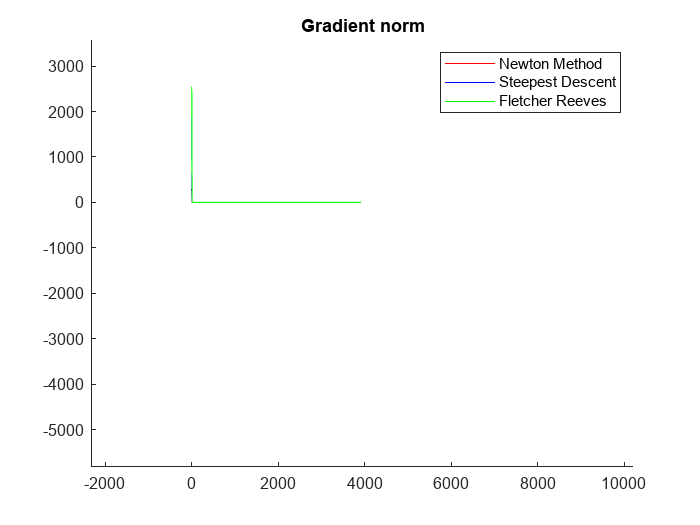

figure(1);
hold on;
title("Gradient norm")
plot(linspace(0,k,k), gfseq, "r")
plot(linspace(0,k_sd,k_sd), gfseq_sd, "b")
plot(linspace(0,k_fr,k_fr), gfseq_fr, "g")
legend(["Newton Method", "Steepest Descent", "Fletcher Reeves"])
hold off

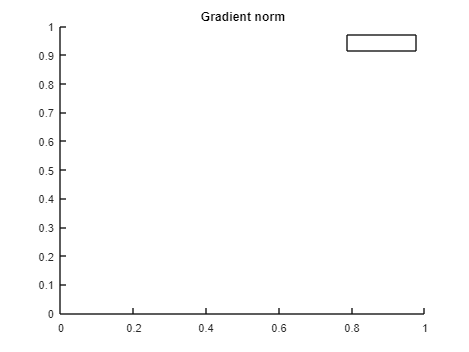

cla

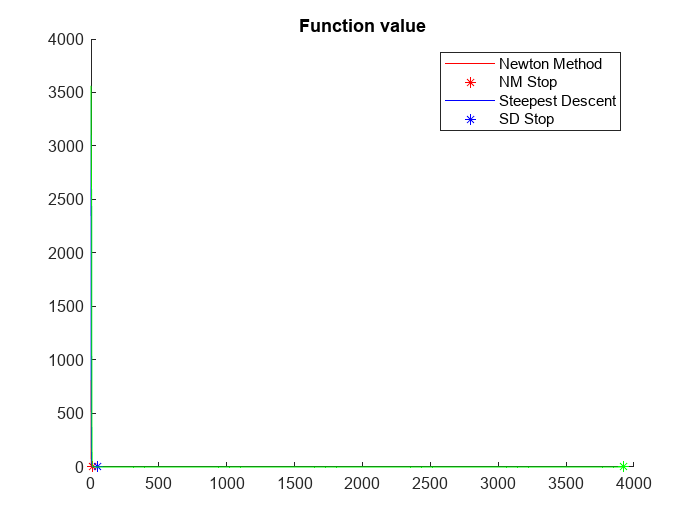

figure(3);
hold on;
title("Function value")
plot(linspace(0,k,k), fseq, "r")
plot(k, fseq(k), "*r")
plot(linspace(0,k_sd,k_sd), fseq_sd, "b")
plot(k_sd, fseq_sd(k_sd), "*b")

plot(linspace(0,k_fr, k_fr), fseq_fr, "g")
plot(k_fr, fseq_fr(k_fr), "*g")
legend("Newton Method","NM Stop", "Steepest Descent", "SD Stop")
hold off;

% disp_int = [-1 1];
% 
% f1_meshgrid = @(X,Y)reshape(f([X(:),Y(:)]'),size(X));
% fcontour(f1_meshgrid, disp_int, 'Fill','on');
% hold on
% h = plot(xseq(1,:), xseq(2,:), '-*r', 'linewidth', 1, 'markersize', 5);
% hold off

% % creation of meshgrid for the contour-plot
% [X1, Y1] = meshgrid(linspace(-2, 2, 500), linspace(-2, 2, 500));
% 
% % computation of the values of f for each point of the mesh
% % Z1 = (1-X1).^2 + 100 * (Y1-X1.^2).^2;
% 
% % Plots
% 
% % simple plot
% fig1_n = figure();
% 
% % contour plot with curve levels for each point in xseq
% % [C1, ~] = contour(X1, Y1, Z1, [1, 10, 50, 100:1000:9000]);
% 
% hold on
% % plot of the points in xseq
% plot([x0(1) xseq(1, :)], [x0(2) xseq(2, :)], '-*', color="r")
% 
% hold off
% title('Inexact Newton')
